%% Modelo
load('modelo_lin.mat');

G = longmod([3, 4], 1);
G.OutputName = {'q', 'theta'};
G.InputName = {'elevator'};

## Pesos para q

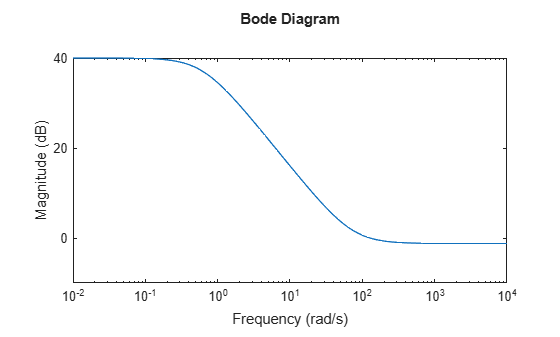

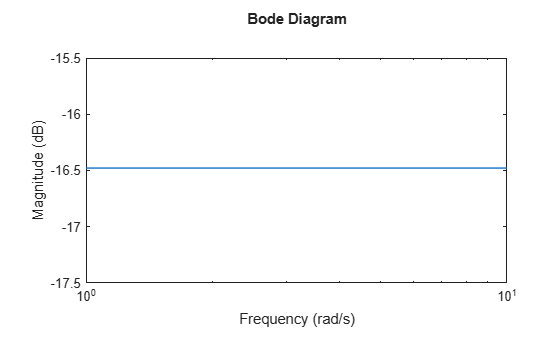

% W1: S <= 1/W1 -> BW >= 8 Hz (se diseña a 10 Hz), error estacionario ~0, rechazo de perturbacion a la entrada hasta 6 Hz, Ms = M1 para buen amortiguamiento
M1_q  = 1.15;
A1_q  = 1e-3;
Wb1_q = 2*pi*10;
W1_q  = tf([1/M1_q Wb1_q], [1 A1*Wb1_q]);
bodemag(W1_q)

% W3: T <= 1/W3 -> roll-off, robustez
M3_q  = 0.01;
A3_q  = 10;
Wb3_q = 2*pi*100;
W3_q  = tf([1/M3 Wb3_q], [1 A3*Wb3_q]);
bodemag(W3_q)

## Pesos para theta

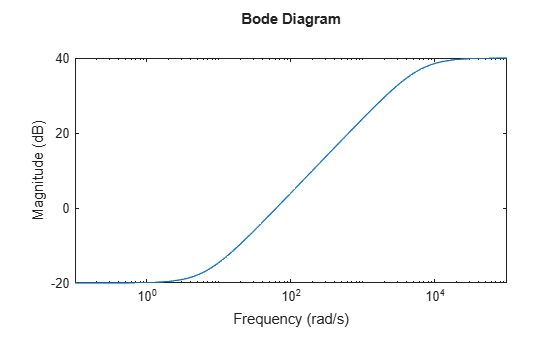

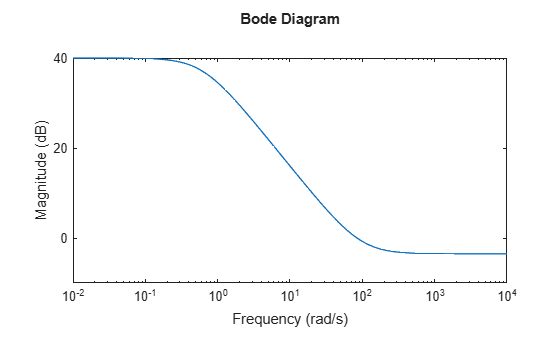

% W1: S <= 1/W1 -> BW >= 8 Hz (se diseña a 10 Hz), error estacionario ~0, rechazo de perturbacion a la entrada hasta 6 Hz, Ms = M1 para buen amortiguamiento
M1_t  = 1.5;
A1_t  = 1e-2;
Wb1_t = 2*pi*10;
W1_t  = tf([1/M1_t Wb1_t], [1 A1_t*Wb1_t]);
bodemag(W1_t)

% W2: K*S <= 1/W2 -> |elevador| <= 30 deg para ref de 40 deg  => u/r <= 0.75
%     sube en alta frecuencia: limita ruido e incertidumbre aditiva a la entrada
Mu_t  = 30/40;
%W2  = (1/Mu_t)*tf([1/(2*pi*) 1], [1/(2*pi*200) 1]);
W2_t = 0.15 * tf(1,1);
bodemag(W2)

% W3: T <= 1/W3 -> roll-off, robustez
M3_t  = 0.01;
A3_t  = 10;
Wb3_t = 2*pi*100;
W3_t  = tf([1/M3_t Wb3_t], [1 A3_t*Wb3_t]);
bodemag(W3_t)

## Planta y Controlador

W1 = blkdiag(W1_q, W1_t)


W1 =
 
  From input 1 to output...
       0.8696 s + 62.83
   1:  ----------------
          s + 0.6283
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       0.6667 s + 62.83
   2:  ----------------
          s + 0.6283
 
Continuous-time transfer function.


W3 = blkdiag(W3_q, W3_t)


W3 =
 
  From input 1 to output...
       100 s + 628.3
   1:  -------------
         s + 6283
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       100 s + 628.3
   2:  -------------
         s + 6283
 
Continuous-time transfer function.



P = augw(G, W1, W2_t, W3);                 % entradas [r; u], salidas [z1; z2; z3; e]

%% Controlador H-infinito
ncont = 1;
nmeas = 1;
[K1, CL, gam1, info] = hinfsyn(P, nmeas, ncont);
disp(['gamma = ' num2str(gam1)])

gamma = 100.005


disp('Polos del controlador'), eig(K1)

Polos del controlador


ans = 1.0e+04 *

  -8.9606 + 0.0000i
  -0.6283 + 0.0000i
  -0.0061 + 0.0016i
  -0.0061 - 0.0016i
  -0.0007 + 0.0000i
  -0.0006 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0001 + 0.0000i


%% Lazo cerrado
L = G*K1;
S = feedback(1, L('theta'));
T = feedback(L('theta'), 1);
KS = K1*S;

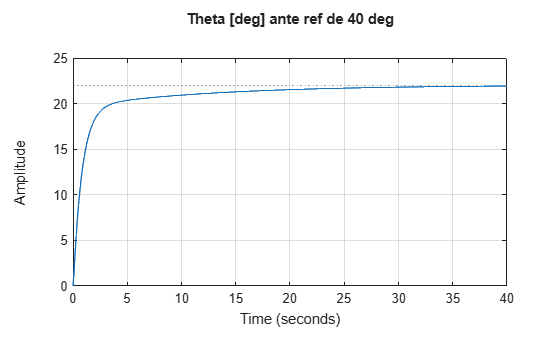

%Figuras
figure(1), step(40*T), grid on, title('Theta [deg] ante ref de 40 deg')

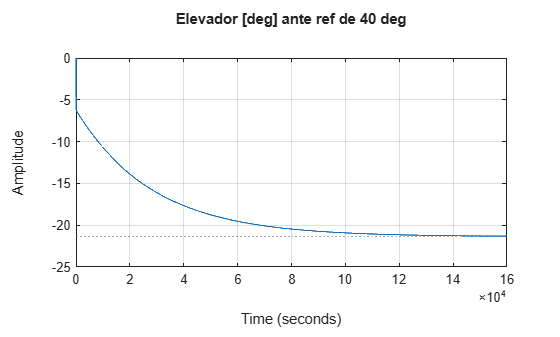

figure(2), step(40*KS), grid on, title('Elevador [deg] ante ref de 40 deg')

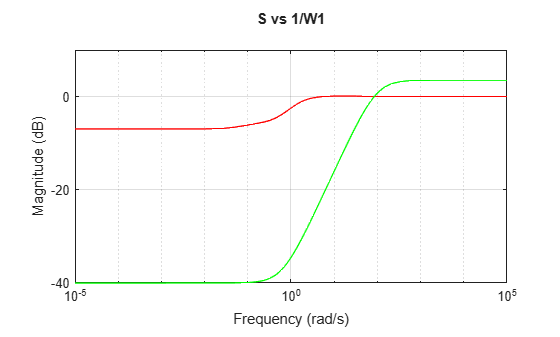


figure(3), bodemag(S,'r', 1/W1_t,'g'), grid on, title('S vs 1/W1')

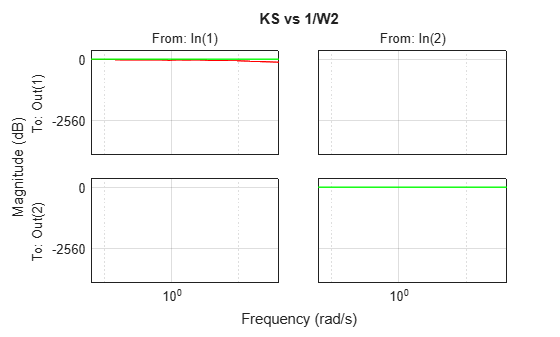

figure(4), bodemag(KS,'r', 1/W2,'g'), grid on, title('KS vs 1/W2')

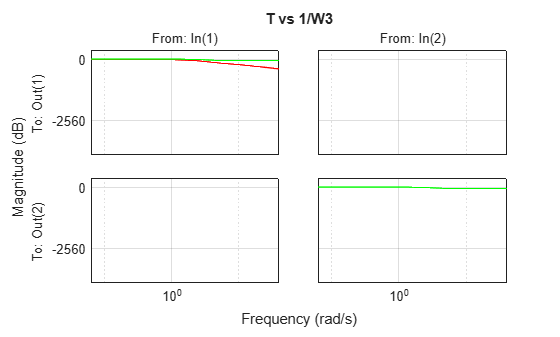

figure(5), bodemag(T,'r', 1/W3,'g'), grid on, title('T vs 1/W3')